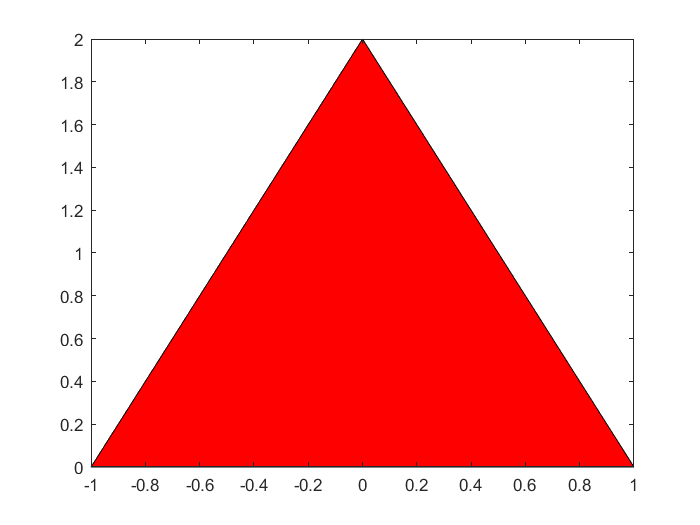

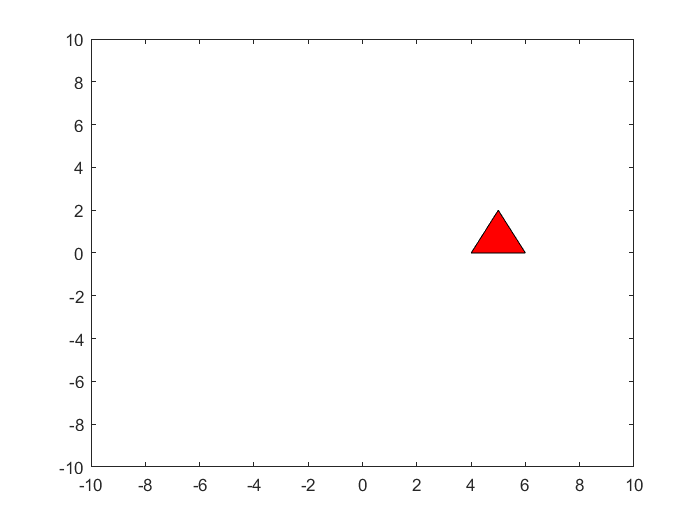

Unrecognized function or variable 'Rot'.

clc; clear; close all;


P1 = [-1 0]';
P2 = [1 0]';
P3 = [0 2]';
A1 = [P1 P2 P3];

fill(A1(1,:), A1(2,:),  'r');
axis([-10 10 -10 10]);
axis square
hold on 
v = [5 0]';
A2 = A1 + v;

fill(A2(1,:), A2(2,:),'w');
hold on 

A3 = Rot(50) * A2;

h = fill(A3(1,:), A3(2,:),'b');

N = 50;

for r = linspace(60,350,N)
    An = Rot(deg2rad(r)) * A2;
    %fill(An(1,:), An(2,:), 'c');
    h.Vertices = An';
    pause(0.1)
end
